lat = round(G2latitude,0);
lon = round(wrapTo360(G2longitude),0);
theta = G2theta;
sigma0 = G2sigma0;
sigma1 = G2sigma1;
pH = G2phtsinsitutp;

floatList = readtable("\\atlas\Chem\ARGO_PROCESSING\DATA\CAL\MBARI_float_list.txt");

floatList = floatList(~isnat(floatList.x1stDate),:);

wmoList = floatList.WMO;

for i = 1:2
    
    disp(wmoList(i))
    DATA = get_FloatViz_data("\\atlas\chem\ARGO_PROCESSING\DATA\FLOATVIZ\QC\"+wmoList(i)+"QC.txt");
    
    %If float isn't equipped with pH, skip the float
    if ~any(contains(DATA.hdr,'pHinsitu[Total]'))
        continue;
    end
    
    % GET SOME RAW INDICES
    DATA.iStn  = find(strcmp('Station', DATA.hdr) == 1);
    DATA.iP    = find(strcmp('Pressure[dbar]', DATA.hdr)  == 1);
    DATA.iT    = find(strcmp('Temperature[°C]', DATA.hdr)  == 1);
    DATA.iS    = find(strcmp('Salinity[pss]', DATA.hdr)  == 1);
    DATA.iD    = find(strcmp('Sigma_theta[kg/m^3]', DATA.hdr) == 1);
    DATA.iZ    = find(strcmp('Depth[m]', DATA.hdr)  == 1);
    DATA.iO    = find(strcmp('Oxygen[µmol/kg]', DATA.hdr)  == 1);
    DATA.iN    = find(strcmp('Nitrate[µmol/kg]', DATA.hdr) == 1);
    DATA.iPH   = find(strcmp('pHinsitu[Total]', DATA.hdr)  == 1);
    DATA.iLat  = find(strcmp('Lat [°N]', DATA.hdr) == 1);
    DATA.iLon  = find(strcmp('Lon [°E]', DATA.hdr) == 1);
    
    DATA_QC = DATA.data(DATA.data(:,DATA.iT+1)~=8 & ...
        DATA.data(:,DATA.iS+1)~=8 & ...
        DATA.data(:,DATA.iD+1)~=8 & ...
        DATA.data(:,DATA.iPH+1)~=8,:);
    
    floatLon = round(DATA.data(:,DATA.iLon),0);
    floatLat = round(DATA.data(:,DATA.iLat),0);
    floatPH = DATA_QC(:,DATA.iPH);
    floatDensity = DATA_QC(:,DATA.iD);

    if i==1
        tblPH = pH(ismember(lon,floatLon)&ismember(lat,floatLat));
        tblSig = sigma0(ismember(lon,floatLon)&ismember(lat,floatLat));
        tblFloatPH = floatPH(ismember(floatLon,lon)&ismember(floatLat,lat));
        tblFloatSig = floatDensity(ismember(floatLon,lon)&ismember(floatLat,lat));
        continue;
    else
        tblPH = [tblPH; pH(ismember(lon,floatLon)&ismember(lat,floatLat))];
        tblSig = [tblSig; sigma0(ismember(lon,floatLon)&ismember(lat,floatLat))];
        tblFloatPH = [tblFloatPH; floatPH(ismember(floatLon,lon)&ismember(floatLat,lat))];
        tblFloatSig = [tblFloatSig; floatDensity(ismember(floatLon,lon)&ismember(floatLat,lat))];
    end
end

     4903026



f1 = figure()

f1 =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 578 560 420]
       Units: 'pixels'

  Show all properties


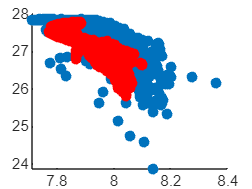


scatter(tblPH,tblSig,'filled')

hold on;

scatter(tblFloatPH,tblFloatSig,'red','filled')